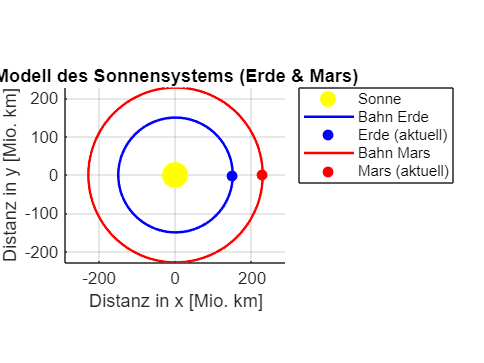

% Skript: Sonnensystem_Modell.m
% Beschreibung: Einfaches numerisches Modell von Erde und Mars (Kreisbahnen)
clear; clc; close all;

%% 1. Parameter definieren (Quelle: Wikipedia)
% Erde
R_Erde = 149.6;     % Mittlerer Bahnradius in Mio. km
T_Erde = 365.25;    % Umlaufzeit in Tagen

% Mars
R_Mars = 227.9;     % Mittlerer Bahnradius in Mio. km
T_Mars = 687;       % Umlaufzeit in Tagen (gerundet)

%% 2. Berechnung der Winkelgeschwindigkeiten
% omega = 2 * pi / T
w_Erde = 2 * pi / T_Erde;
w_Mars = 2 * pi / T_Mars;

%% 3. Zeitvektor erstellen
% Wir simulieren 2 Jahre (ca. 730 Tage)
t = 0:1:730; 

%% 4. Berechnung der Bahnkurven (Trajektorien)
% Erde
x_Erde = R_Erde * cos(w_Erde * t);
y_Erde = R_Erde * sin(w_Erde * t);

% Mars
x_Mars = R_Mars * cos(w_Mars * t);
y_Mars = R_Mars * sin(w_Mars * t);

%% 5. Visualisierung
figure('Name', 'Sonnensystem Modell: Erde und Mars');
hold on; grid on; axis equal;

% Sonne im Ursprung
plot(0, 0, 'yo', 'MarkerSize', 15, 'MarkerFaceColor', 'yellow', 'DisplayName', 'Sonne');

% Bahn und Position der Erde
plot(x_Erde, y_Erde, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Erde');
plot(x_Erde(end), y_Erde(end), 'bo', 'MarkerFaceColor', 'blue', 'DisplayName', 'Erde (aktuell)');

% Bahn und Position des Mars
plot(x_Mars, y_Mars, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Bahn Mars');
plot(x_Mars(1), y_Mars(1), 'ro', 'MarkerFaceColor', 'red', 'DisplayName', 'Mars (aktuell)');

% Beschriftung
xlabel('Distanz in x [Mio. km]');
ylabel('Distanz in y [Mio. km]');
title('Modell des Sonnensystems (Erde & Mars)');
legend('Location', 'northeastoutside');

hold off;

%Aufgabe 2
% 1 AE (Astronomische Einheit) ca. 149.6e9 Meter
pos_erde = [149.6e9, 0, 0];      
pos_mars = [227.9e9, 0, 0];      

sonden_pos = [180e9, 10e9, 0];   

% Aufruf der Routine
g_vektor = berechne_gravitationsfeld(sonden_pos, pos_erde, pos_mars);

% Ausgabe
fprintf('Resultierender Feldvektor g [m/s^2]:\n');

Resultierender Feldvektor g [m/s^2]:


disp(g_vektor);

   -0.0041   -0.0002         0




fprintf('Betrag der Feldstärke |g|: %e m/s^2\n', norm(g_vektor));

Betrag der Feldstärke |g|: 4.083798e-03 m/s^2




function g_total = berechne_gravitationsfeld(sonde_pos, pos_erde, pos_mars)
    G = 6.67430e-11;       % Gravitationskonstante 
    
    M_sonne = 1.9884e30;   % Masse der Sonne in kg
    M_erde  = 5.9722e24;   % Masse der Erde in kg
    M_mars  = 6.39e23;     % Masse des Mars in kg
    
    pos_sonne = [0, 0, 0]; % Sonne im Ursprung des Koordinatensystems

    %Gravitationsfeld der Sonne
    %Vektor von der Sonne zum Punkt
    r_vec_sonne = sonde_pos - pos_sonne;
    dist_sonne = norm(r_vec_sonne); % Betrag des Abstands
    
    if dist_sonne == 0
        error('Der Punkt befindet sich im Zentrum der Sonne');
    end
    
    g_sonne = -G * M_sonne * (r_vec_sonne / dist_sonne^3);

    %Erde und Mars
    % Berechnung Feld Erde
    r_vec_erde = sonde_pos - pos_erde;
    dist_erde = norm(r_vec_erde);
    
    if dist_erde > 0
        g_erde = -G * M_erde * (r_vec_erde / dist_erde^3);
    else
        g_erde = [0 0 0]; % Punkt ist im Zentrum der Erde
    end
    
    % Berechnung Feld Mars
    r_vec_mars = sonde_pos - pos_mars;
    dist_mars = norm(r_vec_mars);
    
    if dist_mars > 0
        g_mars = -G * M_mars * (r_vec_mars / dist_mars^3);
    else
        g_mars = [0 0 0]; % Punkt ist im Zentrum des Mars
    end

    %% 4. Superposition (Vektoraddition)
    g_total = g_sonne + g_erde + g_mars;

end